## **Experimento 2 - Codificacao Com Realimentacao**

#### Bruno Hashimoto - 10715628

#### Guilherme Fernandes - 10297272

%lambda = 1; => W = 1;
[sinal, ~] = audioread('antarctica.wav');
sinal = sinal(1:11200);

L = 240; % num de amostras dos quadros (30ms)
N = 80; % num de amostras para trechos (10ms)
fnc_base = randn(N, 512); % 512 funcoes aleatorias 
K = 2;  % num de funcoes base
p = 10; % ordem do LPC

zs = zeros(p, 1);
sinal_gerado = [];

for start=1:N:length(sinal)-L+N
    % define trecho de 240 amostras
    % a)
    trecho = sinal(start:(start+L-1), 1);
    [a_trecho, ~] = lpc(trecho .* hamming(L), p);

    % b)
    %subquadro de comprimento 80 usando as amostras centrais do quadro atual
    subquadro = trecho(N+1:2*N, 1);
    
    % c) filtre todas as sequencias de Q por ak
    fnc_base_filt = filter(1, a_trecho, fnc_base);

    % d) melhore a transicao entre os quadros
    [y0, ~] = filter(1, a_trecho, zeros(N,1));

    % e) calcule o sinal e0
    e0 = subquadro - y0;

    % f) 
    [ganhos, indices] = find_Nbest_components(e0, fnc_base_filt, K); % sinal, codebook_vectors, N

    % g) defina o sinal de excitacao
    d = fnc_base(:,indices)*ganhos;% * 2^-2;

    % 
    [sinal_saida, zs] = filter(1, a_trecho, d, zs);

    sinal_gerado = [sinal_gerado; sinal_saida];
end

Plot do sinal gerado em comparação com o sinal quantizado.

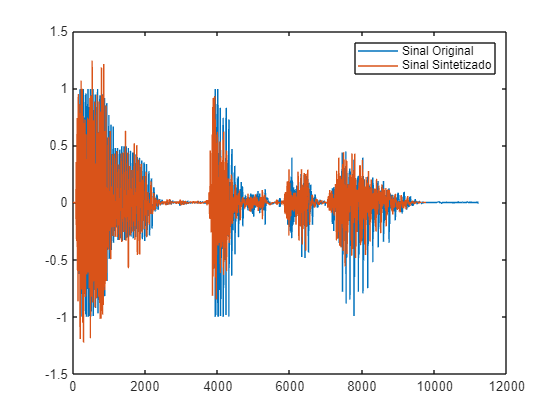

figure;
plot(sinal);
hold on;
plot(sinal_gerado);
legend("Sinal Original","Sinal Sintetizado");

Mesma processamento mas com quantização.

sinal_gerado_quant = [];
zs = zeros(p, 1);

for start=1:N:length(sinal) - 2*N

    trecho = sinal(start:start+L-1, 1);
    % a)
    [a_trecho, ~] = lpc(trecho .* hamming(L), p); % ignora o sig2
    a_quant = quantize3(a_trecho, 7); % quantize o preditor com 7bits

    % b)
    %subquadro de comprimento 80 usando as amostras centrais do quadro atual
    subquadro = trecho(N+1:2*N, 1);
    
    % c) filtre todas as sequencias de Q por ak
    fnc_base_filt = filter(1, a_quant, fnc_base);

    % d) melhore a transicao entre os quadros
    [y0, zs] = filter(1, a_trecho, zeros(N,1), zs);

    % e) calcule o sinal e0
    e0 = subquadro - y0;

    % f) 
    [ganhos, indices] = find_Nbest_components(e0, fnc_base_filt, K); % sinal, codebook_vectors, N
    ganhos_quant = quantize3(ganhos, 5) ; % quantizado com 5bits

    % g) defina o sinal de excitacao
    d = fnc_base(:,indices)*ganhos_quant;

    % 
    [sinal_saida, zs] = filter(1, a_quant, d, zs);
    sinal_gerado_quant = [sinal_gerado_quant; sinal_saida];
end

Plot do sinal original em comparação com o sinal sintetizado quantizado.

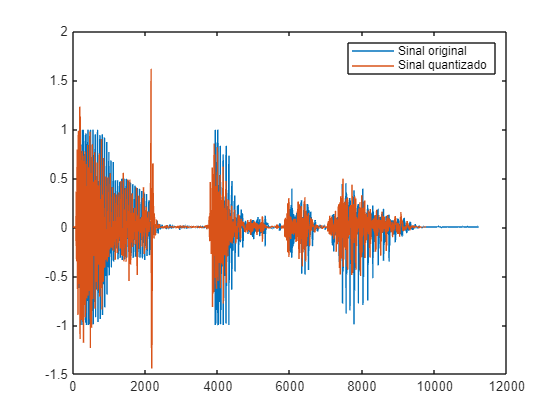

figure;
plot(sinal);
hold on;
plot(sinal_gerado_quant);
legend('Sinal original', 'Sinal quantizado');⁠